clc
close all
clearvars
MN3510_MF1302R_0 = readtable('UDP_2021-11-16_144348.csv');

MN3510_MF1302R_90 = readtable('UDP_2021-11-16_145014.csv');

MN3510_MF1302R_0_w = readtable('meas30.txt');
MN3510_MF1302R_90_w = readtable('meas31.txt');


shift_1 = 0%0.3;

shift_1 = 0

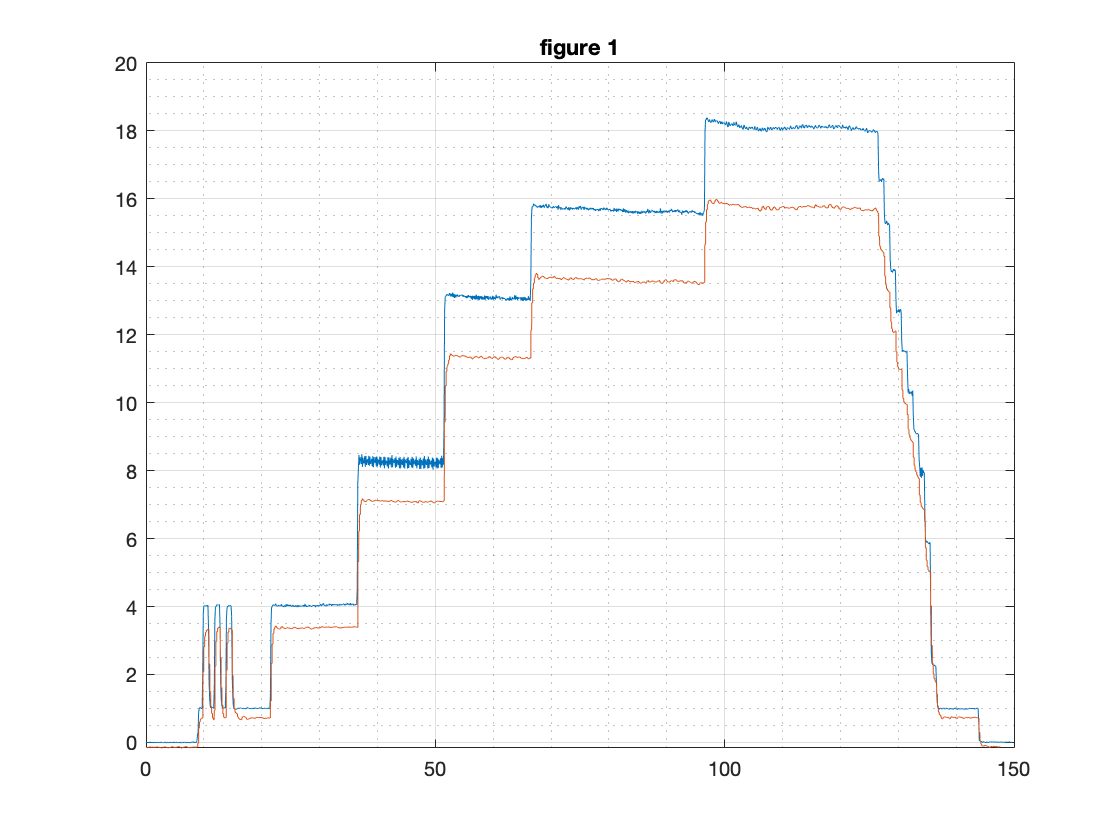

averager = MN3510_MF1302R_0_w.Var6(1);
figure(1)
clf
plot(MN3510_MF1302R_0_w.Var1+shift_1,MN3510_MF1302R_0_w.Var6-averager)
hold on
plot(MN3510_MF1302R_0.Time_s_,MN3510_MF1302R_0.Thrust_N_)
title('figure 1')
grid on
grid minor

as  = MN3510_MF1302R_0_w.Var12;
tta = MN3510_MF1302R_0_w.Var14;
t_w   = MN3510_MF1302R_0_w.Var1;
t_rc  = MN3510_MF1302R_0.Time_s_;

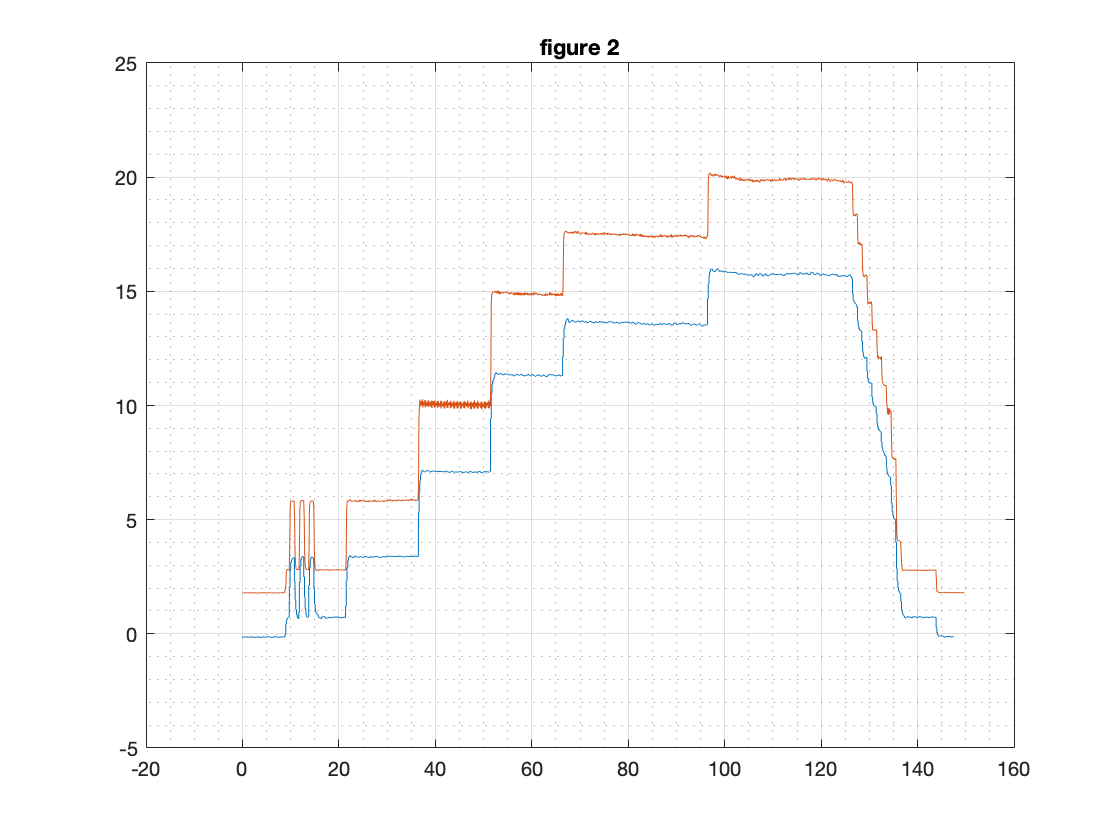

delay_0 = syncher(t_w,MN3510_MF1302R_0_w.Var6,t_rc,MN3510_MF1302R_0.Thrust_N_,1);

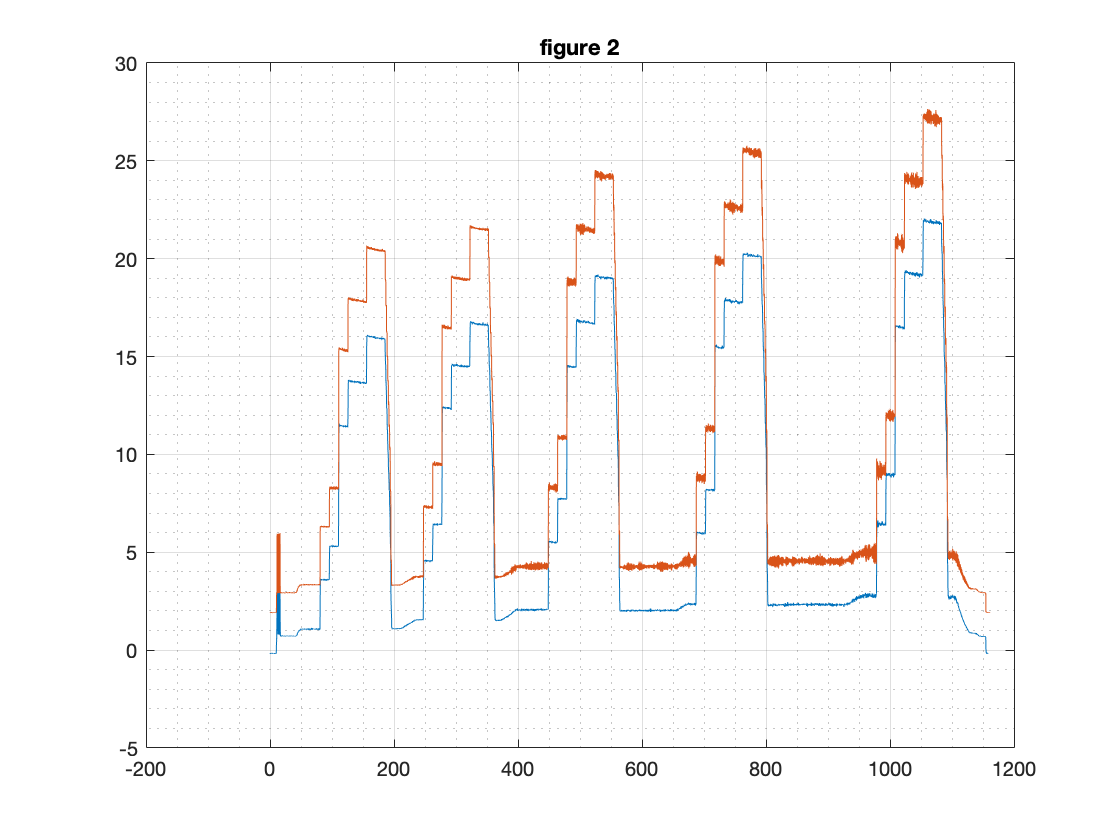

delay_90 = syncher(MN3510_MF1302R_90_w.Var1,MN3510_MF1302R_90_w.Var6,MN3510_MF1302R_90.Time_s_,MN3510_MF1302R_90.Thrust_N_,1);

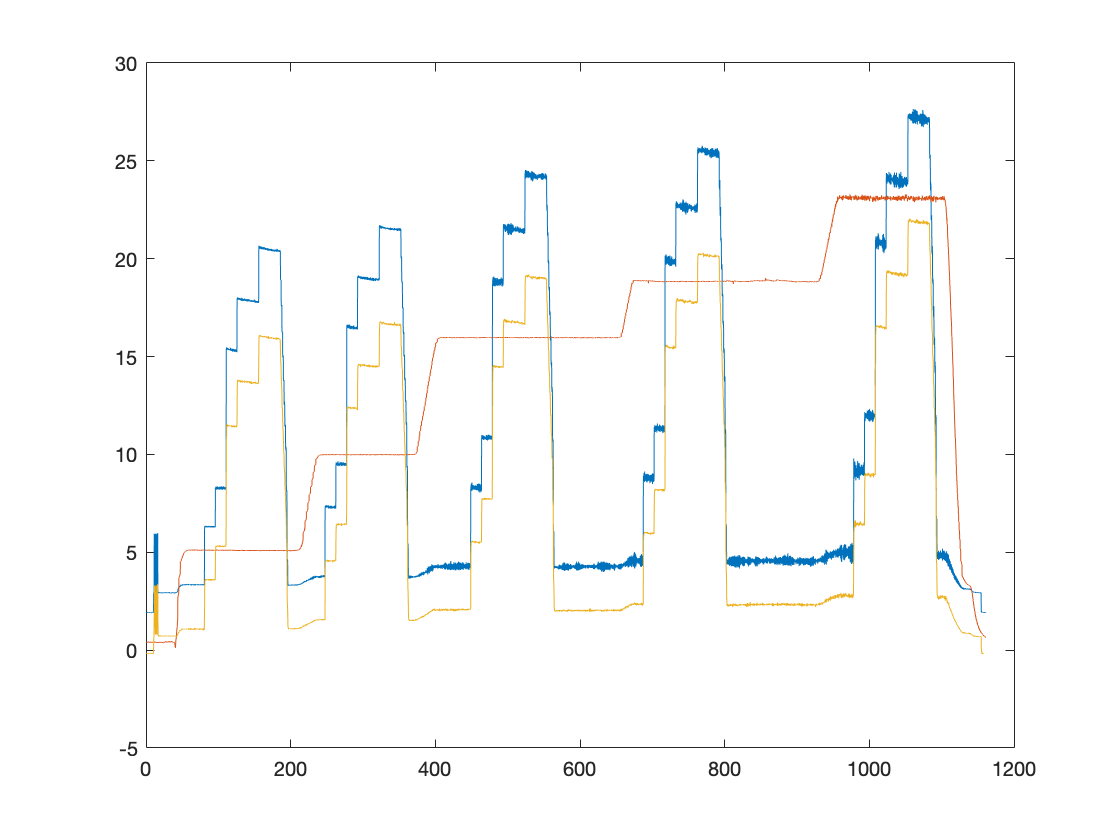

figure(5)
clf
plot(MN3510_MF1302R_90_w.Var1,MN3510_MF1302R_90_w.Var6)
hold on
plot(MN3510_MF1302R_90_w.Var1,MN3510_MF1302R_90_w.Var12)
plot(MN3510_MF1302R_90.Time_s_,MN3510_MF1302R_90.Thrust_N_)

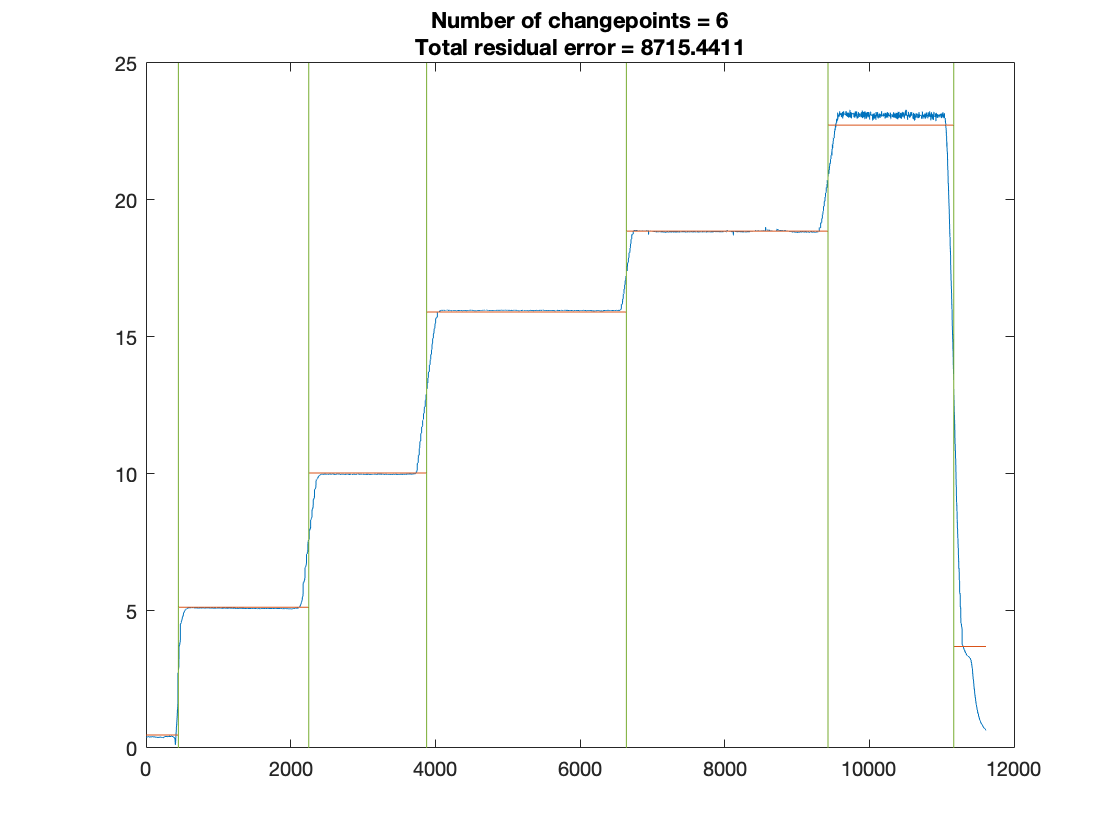



figure(6)
clf
findchangepts(MN3510_MF1302R_90_w.Var12,'MaxNumChanges',6)

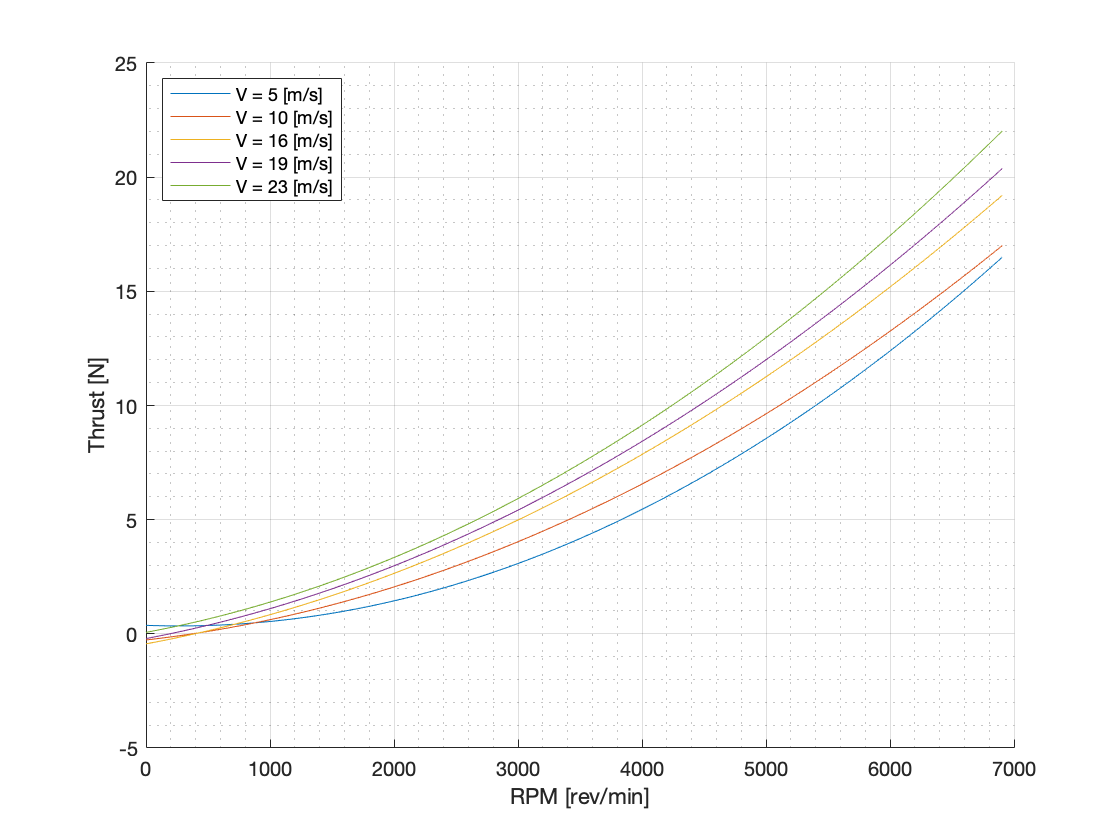

v_q = [5,10,16,19,23];
ipt = findchangepts(MN3510_MF1302R_90_w.Var12,'MaxNumChanges',6);
deg=2;
polycoeffs = zeros(deg+1, size(v_q,2));
rpm_lim = [min(MN3510_MF1302R_90.MotorElectricalSpeed_RPM_) max(MN3510_MF1302R_90.MotorElectricalSpeed_RPM_)];
rpm_q = linspace(rpm_lim(1),rpm_lim(2),100);
figure(7)
clf
hold on 
for i = 1:size(v_q,2)
    idx_s = find(MN3510_MF1302R_90.Time_s_>=(MN3510_MF1302R_90_w.Var1(ipt(i))+delay_90).',1,'first');
    idx_e = find(MN3510_MF1302R_90.Time_s_>=(MN3510_MF1302R_90_w.Var1(ipt(i+1))+delay_90).',1,'first');
    
    polycoeffs(:,i) = polyfit(MN3510_MF1302R_90.MotorElectricalSpeed_RPM_(idx_s:idx_e),MN3510_MF1302R_90.Thrust_N_(idx_s:idx_e),deg);
    plot(rpm_q,polyval(polycoeffs(:,i),rpm_q))
end
legendStrings = "V = " + string(round(v_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')

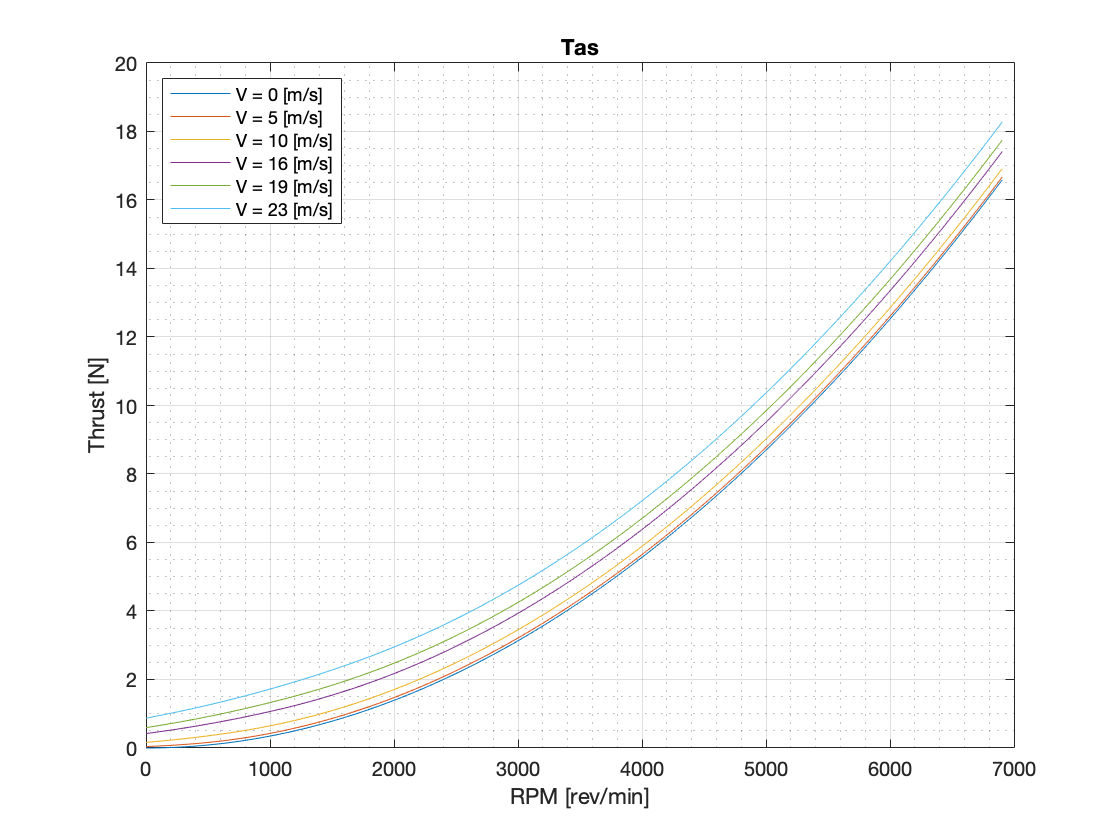

d = 339.8e-3;
r = d/2;
rpm2rads= 2*pi/60;
Vt_q =[0  5 10 16 19 23];
range= (MN3510_MF1302R_0.MotorElectricalSpeed_RPM_==MN3510_MF1302R_0.MotorOpticalSpeed_RPM_);

rcCL = 1.06 * mean(MN3510_MF1302R_0.Thrust_N_(range)./(MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(range)*rpm2rads).^2 .* (3/r^3));

fun = @(x,rev,as,rcCl) 0.5*rcCL*(rev*x+as).^2+0.5*rcCL*max(0,(rev*x-as)).^2;


T_as = zeros(size(rpm_q,2),size(Vt_q,2));
for k=1:size(rpm_q,2)
    for j=1:size(Vt_q,2)
        T_as(k,j)= integral(@(x) fun(x,rpm_q(k)*rpm2rads,Vt_q(j),rcCL),0,r);
    end
end
figure(8)
clf
plot(rpm_q,T_as.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
grid on
grid minor
title('Tas')

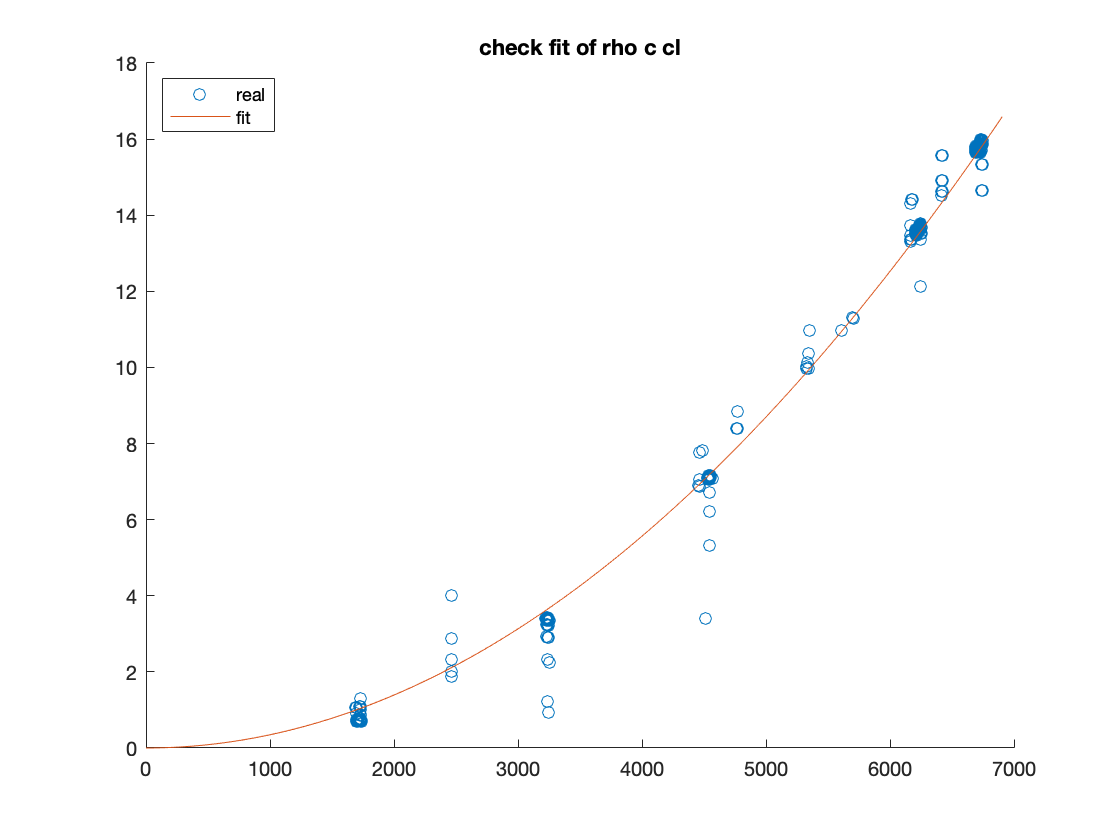



figure(101)
clf
title('check fit of rho c cl')
hold on 
scatter(MN3510_MF1302R_0.MotorElectricalSpeed_RPM_(range),MN3510_MF1302R_0.Thrust_N_(range))
plot(rpm_q,T_as(:,1))
legend('real','fit','Location','northwest')

rpm_elect = MN3510_MF1302R_0.MotorElectricalSpeed_RPM_;
rpm_elect(rpm_elect==0)=0.001;
[rpm_elect,tf] = rmoutliers(rpm_elect,'movmean',200);

time_elect = MN3510_MF1302R_0.Time_s_;
time_elect(tf)=[];
thrust_elect = MN3510_MF1302R_0.Thrust_N_;
thrust_elect(tf)=[];
